clc
clear all
close all

% Calculates E(x,y,k,theta) from energy balance equation.

% The equation to solve is:
% E(x,y,k,th)_{n+1} = E(x,y,k,th)_n + delt * (-Cg cos(th)dE/dx -Cg sin(th)dE/dy + Sin + Snl - Sds).
% Dimensions of x, y, k, th are m, n, ,o, p.

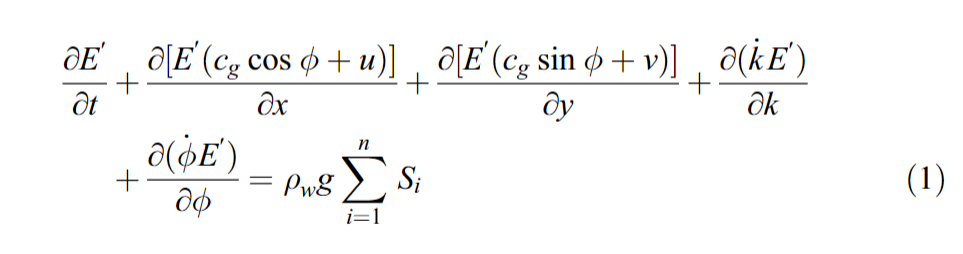

First term = time evolution of local spectrum = 

Second + Third term = spatial evolution of spectrum mulitplied by the vector sum of the group velocity and the current = 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tic

% prepare log file for commands
dfile=[datestr(now,'mmddyyyy_HHMMSS'),'_FetchLaws.txt'];
diary(dfile);
diary on;

% create output directory for results
parentFolder = fileparts(pwd);
TitanResults = sprintf('%s\\Titan%s', pwd);
if ~exist(TitanResults, 'dir')
  mkdir(TitanResults);
end

## MODEL SET UP %%

## global constants %%

kappa = 0.4; % Von-Karman constant

## grid %%

m = 31; % number of gridpoints in x-direction
n = 15; % number of gridpoints in y-direction
p = 288; % number of angular (th) bins. Note: p must be factorable by 8 for octants.
o = 25; % numner of frequency bins

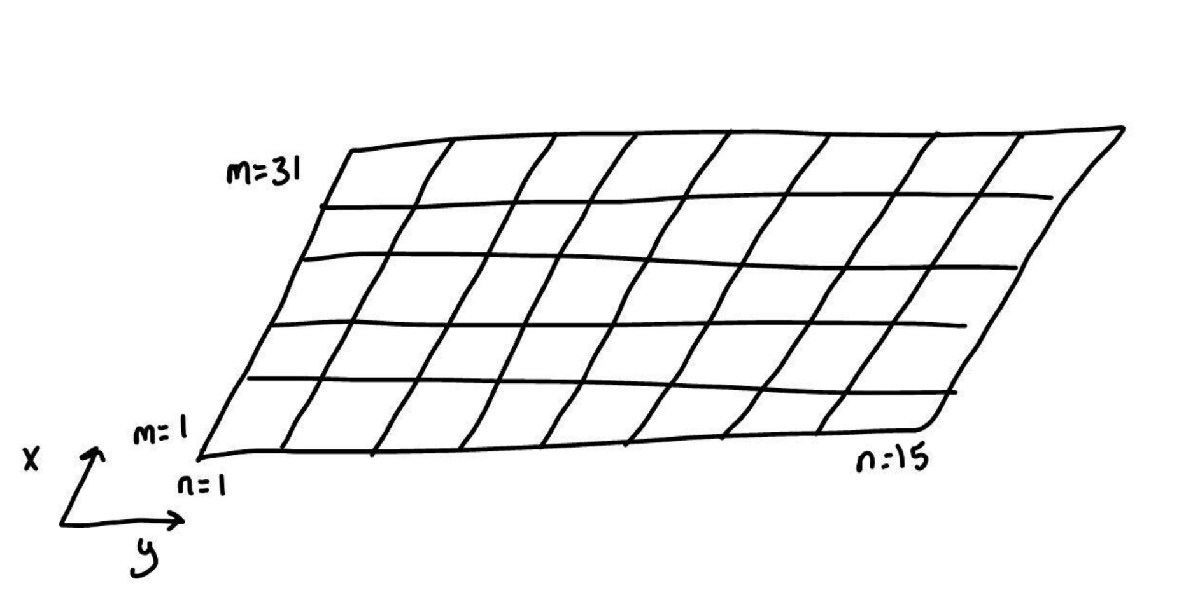

## delt:

mindelt = 0.0001; % Minimum delt to minimize oscillations of delt to very small values
maxdelt = 2000.0; % Limit of delt to prevent large values as wind ramps up at startup

## frequency limits:

f1 = 0.05;
f2=35;

## frequency bins

oa = 7; % top bin advected
ol = 1:oa; % bin numbers for long frequencies
os = oa+1:o; % bin numbers for short frequencies.
op = [p/2+1:p 1:p/2]; % opposite direction from p 
orm = p:-1:1; % reflected directions (100% reflection at y-boundaries)

% wind profile:
zref = 20; % reference height for wind speed [m]
z = 10; % height of measured wind speed [m]
wfac = 0.035; % winddrift fraction of Uz

Wind profile obeys law of wall above liquid surface:

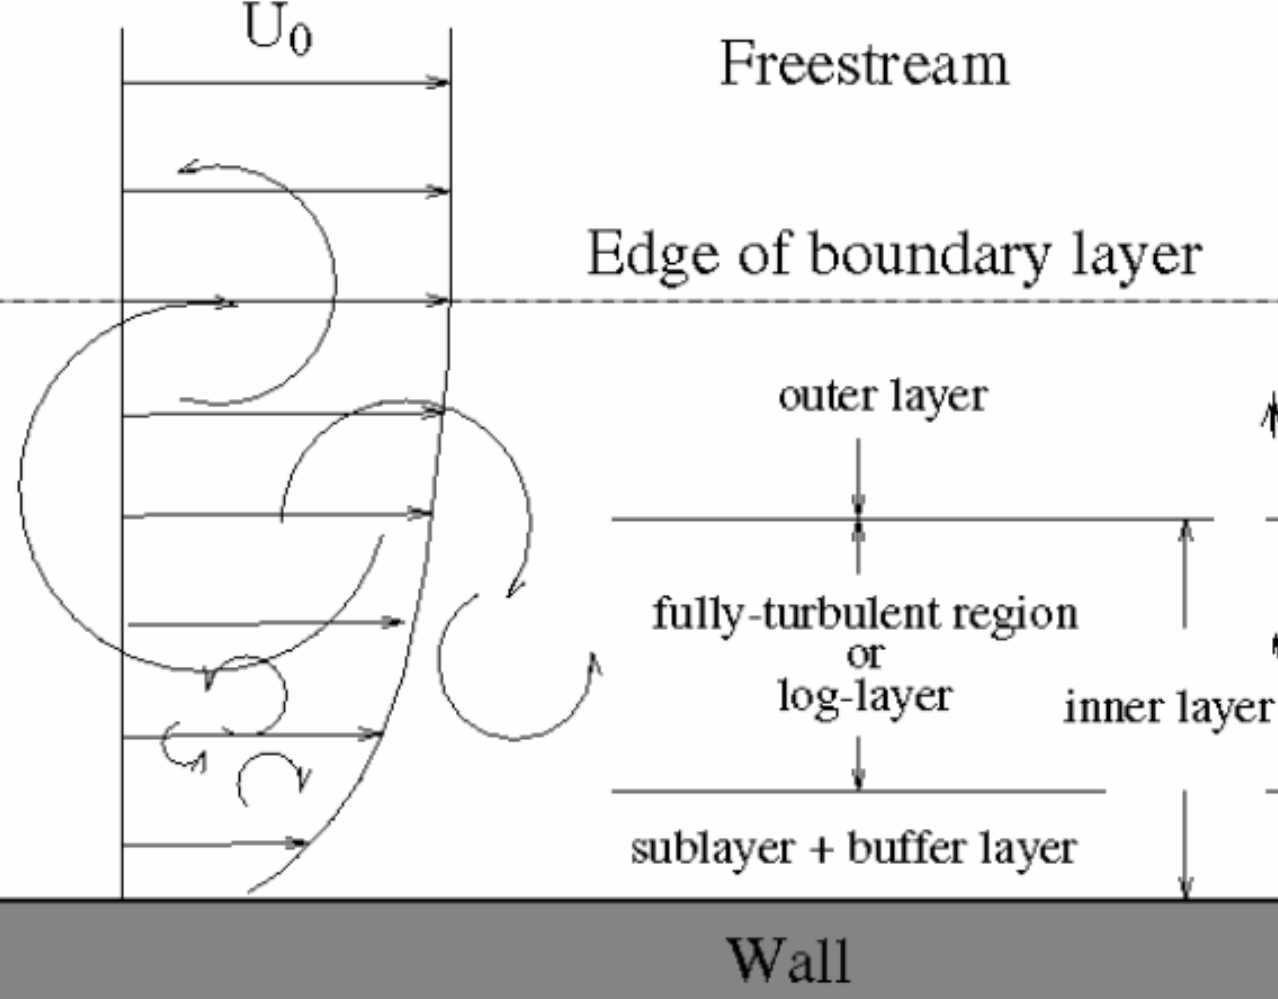

## LAKE OF INTEREST %%

Titan, Punga Mare

long = 29; % longitude
lati = 8; % latitude
nu = 0.0031/1e4; % kinematic viscotity [m2/s] for pure methane
sfcT = 0.018; % surface tension of lake [N/m]
rhow = 465; % density of liquid [kg/m3]

## TITAN CONSTANTS %%

sfcpress = 1.5*[101300]; % surface pressure [Pa].
sfctemp = 92; % surface temperature [K]
kgmolwt = 0.028; % gm molecular weight [Kgm/mol]
RRR = 8.314; % Universal gas constant [J/K/mol]
rhoa = sfcpress*kgmolwt/(RRR*sfctemp); % air density [kg/m3]
g = 1.35; % gravity [m/s2]
nua = 0.0126/1e4; % atmospheric gas viscosity [m2/s]
rhorat = rhoa/rhow; % air/water density ratio

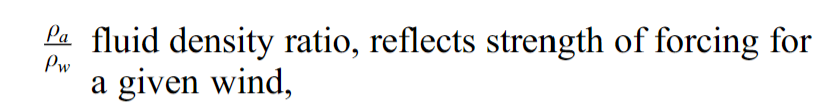

## WIND CLIMATE %%

gust = 0; % Gust factor applied to wind at each time step
UUvec = [0.4:.1:3.3]; % wind velocities of interest [m/s]
wind_direction = 0; % direction of incoming wind
Cd=1.2*ones(n,n); % coefficient of friction is uniform over entire grid at 1.2

## wavenumber:

kutoff = 1000; % wavenumber cut-off due to Kelvin-Helmholtz
kcg = sqrt(g*rhow/sfcT); % wavenumber of slowest waves aka capillary-gravity wave minimum
kcgn = 1.0*kcg; % n power min is not shifted wrt kcg
kcga = 1.15*kcg; % a min is shifted above kcg

## wave angle

waveang = ([0:p-1]-p/2+0.5)*(360/p)*(pi/180);
waveang = repmat(waveang,[o 1 m n]);
waveang=shiftdim(waveang,2);

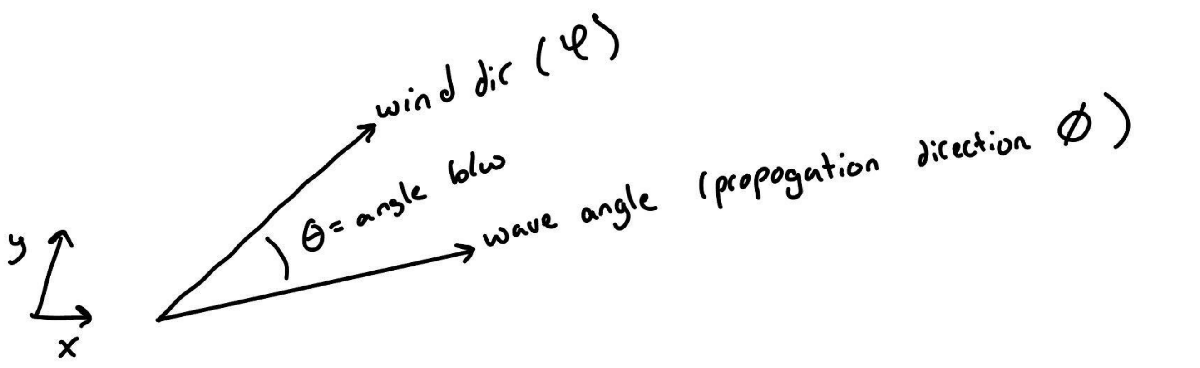

% theta
th = ([0:p-1]-p/2+0.5)*(360/p)*(pi/180);
tth = ([0:p-1])*(360/p)*(pi/180); % angular difference between short waves and longer waves.

## indices for refraction rotation.

cw = [p 1:p-1];
ccw = [2:p 1];

## upwave indices for advective term.

xp = [1 1:m-1];
yp = [1 1:n-1];
xm = [2:m m];
ym = [2:n n];

## not sure?

cp = find(cos(th) > 0);
cm = find(cos(th) < 0);
sp = find(sin(th) > 0);
sm = find(sin(th) < 0);

% reshape not sure
cth = repmat(cos(th),[o 1 m n]);
cth=shiftdim(cth,2);
sth = repmat(sin(th),[o 1 m n]);
sth=shiftdim(sth,2);
cth2 = repmat(cos(tth).^2,[o 1 m n]);
cth2=shiftdim(cth2,2);

## Constant coefficient (fractions applied to terms from fitting with experiment/observations)

mss_fac = 240; % MSS adjustment to Sdiss. 2000 produces very satisfactory overshoot, 400 does not
Sds_fac = 1.0;% This is fac with variable power nnn in Sds.
Sdt_fac = 0.001;
Sbf_fac = 0.002;% Select for bottom roughness. 0.004 is for smooth sandy bottom as in GOM.

## Geographic deltas?

Delx = 1000.0; % Titan [m]
Dely = 1000.0; % Titan [m]
dely = Dely*ones(m,n,o,p);
delx = Delx*ones(m,n,o,p);
mindelx = min(squeeze(delx(1,:,1,1)));

## Time to run model

numdays = 1;
Time = 10000; % full time to run
Tsteps =2; % number of times run?
slostart = 1; % what is this?

% for saving data
file = 1; % for filename 

% something for time evolution of model
explim = 0.1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## LAKE GEOMETRY

% LAKE EXAMPLE 1: Constant Depth
D = 100*ones(m,n); % constant liquid depth [m]

% LAKE EXAMPLE 2: Conical Island (how is this a cone?)
%
%ccm=36; % x-location of island
%ccn=26; % y-location of island
%
%D=zeros(m,n); % initialize depth array
% 
% for j1=1:m
%     for j2=1:n
%         D(j1,j2) = 2*abs((j1-ccm) + 1i*(j2-ccn)) - 9;
%     end
% end


D(D<=0) = 0; % all negative depths should be set to zero

% lateral boundaries are absorptive
D(:,1)=0;
D(1,:)= 0;
D(:,end)=0;
D(end,:)=0;

## ocean currents (no currents for now)

Uer=0*D + 0.0; % Eastward current [m/s]
Uei=0*D + 0.0; % Northward current [m/s]

## PLOT OF BATHYMETRY

[xplot,yplot] = meshgrid(1:m,1:n);
figure;
surf(xplot',yplot',D,'EdgeColor','k')
myc = colorbar;
myc.Label.String = 'Liquid Depth [m]';
title('Lake Model Bathymetry')

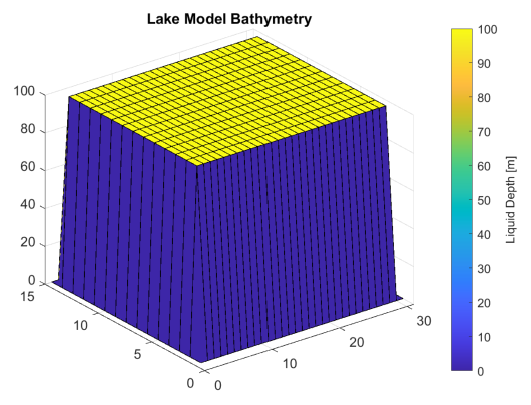


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Snl %%

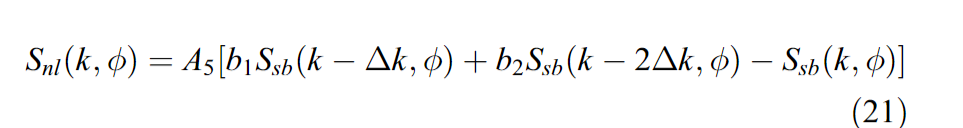

(1) Spilling breakers:

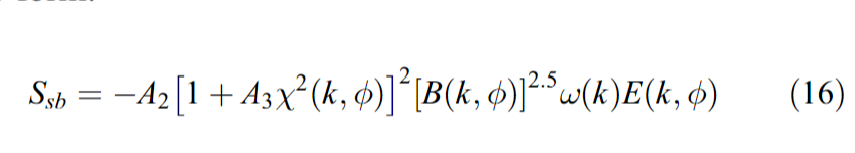

% dominant frequency (I think)
dlnf=(log(f2)-log(f1))/(o-1);
f = exp(log(f1)+[0:o-1]*dlnf);
dom = 2*pi*dlnf.*f;

% diffusion in two frequencies (bf1, bf2) and in two directions (bt1, bt2)
%   bf1 + bf2 = 1
%   bt1 + bt2 = 1
bf1 = exp(-15.73*dlnf*dlnf);

bf2 = exp(-15.73*4*dlnf*dlnf); 

bf1a = bf1/(bf1 + bf2);
bf2 = bf2/(bf1 + bf2);
bf1 = bf1a;

% Compute Snl_fac (downshifting is not a function of A)
A = exp(dlnf);
B = A.*A;
fac = bf1.*(1-1/B) + bf2.*(1-1./B.^2);
Snl_fac = ((1.0942/A)^1.9757)/fac;

fprintf('Snl_fac: %.3f\n',Snl_fac);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Sdiss %%

% initialize for computing wavenumbers at each depth in the x,y grid

wn(:,:,:) = ones(m,n,o);
nnn(:,:,:) = ones(m,n,o);
ann(:,:,:) = ones(m,n,o);

addpath 'C:\Users\schne\OneDrive\Desktop\Main\Work\MIT\Github_Repos\umwm_titan' % need to add wavegkt() function call

for jm = 1:m
    for jn = 1:n
        if D(jm,jn) > 0
            wn(jm,jn,:) = WAVEKgT(f,D(jm,jn),g,sfcT,rhow,1e-4); % wave number 
            nnn(jm,jn,:) = 1.2 + 1.3*(abs(2 - (1+3*(wn(jm,jn,:)./kcgn).^2)./(1+(wn(jm,jn,:)./kcgn).^2)).^2.0); % Power of Sds
            ann(jm,jn,:) = 0.04 + 41.96*(abs(2 - (1+3*(wn(jm,jn,:)./kcga).^2)./(1+(wn(jm,jn,:)./kcga).^2)).^4.0); % Power of Sds
        end
    end
end

% reshape the matrix
wn = repmat(wn,[1 1 1 p]);
nnn = repmat(nnn,[1 1 1 p]);
ann = repmat(ann,[1 1 1 p]);
nnn = (2.53/2.5).*nnn;
nnninv = 1./nnn;
D=repmat(D,[1 1 o p]);
f=repmat(f',[1 p m n]);
f=shiftdim(f,2);
dom=repmat(dom',[1 p m n]);
dom=shiftdim(dom,2);


% wave phase velocity
c=(2*pi*f)./wn;
c(D<=0) = 0; % set phase velocity for negative depth to zero

% wave celerity
Cg=zeros(size(c)); % initialize
Cg(D>0) = c(D>0)./2.*(1 + 2*wn(D>0).*D(D>0)./sinh(2*wn(D>0).*D(D>0)) + 2*sfcT.*wn(D>0)./rhow./(g./wn(D>0) + sfcT.*wn(D>0)./rhow)); % Group velocity for all waves [m/s]
Cg(D<=0) = 0;
cgmax = max(max(max(max(Cg))));

% wave frequency?
dwn = ones(m,n,o,p); 
dwn(D>0)=dom(D>0)./abs(Cg(D>0));

% half wavelength
l2=abs(c)./f/2; %wavelength/2;
lz=abs(c)./f/2/pi; % wavelength/2/pi: kz = 1 for drift current action;

% Set half wavelength terms > zref equal to zref 
l2(l2 > zref) = zref;
lz(lz > zref) = zref;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

E = zeros(m,n,o,p); % initializing the energy term in x,y,k,theta with zeros
% Set delt by Courant condition (to enforce stability during time evolution in the finite differencing scheme)
Ccg = Cg + Uer.*cth + Uei.*sth;
delt = 0.7 * mindelx / cgmax; % advection is limited by the Courant condition for stability


% save data to mat file
eval(['save Titan/Titan_',int2str(file),'_ref m n o p f f wn dwn D Uei Uer Cg c delx dely waveang'])
file = file - 1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

idx = 1; % for frame for gif

for iii = 1:numel(UUvec) % iterate through all wind velocities of interest

    fprintf('Wind velocity: %.2f\n',UUvec(iii));

    file = file + 1; % used for saving data to a specific filename and number
    modt = 0; % something for the time iteration

    U = UUvec(iii).*ones(m,n); % initialize wind vector to have same velocity everywhere on the grid
    Cd = 1.2*ones(m,n); % initialize Cd

    U_z = U + 0.005; % need this small addition to avoid division by zero

    windir =  repmat(wind_direction*ones(m,n),[1 1 o p]); % direction vector map of incoming wind (here it is set to be all uniform direction)

    Cd(U>11) = 0.49 +.065.*U(U>11); % for some reason
    Cd=Cd./1000; % for some reason

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    for t = 1:Tsteps
        
        sumt = 0; % used for iterating 
        tplot = -1; % counter for plotting a figure every tenth loop
        Newdelt = []; % initialize something

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        while((Time - sumt) > 0)

            tplot = tplot + 1;

            % wind velocity profile above an interface
            if gust ~= 0 
                U = U.*(1 + gust*randn(size(U))); % adds a random gust to the wind vector field
            end
            Ul = real(U_z.*sqrt(Cd)); % wind friction velocity 
            Ustar = Ul; % save copy to use elsehwere
            U_10 = 2.5*Ustar.*log(10/z) + U_z; % wind velocity profile according to the Law of the Wall
            ustarw = Ustar .* sqrt(rhorat); % something related to shear stress
            Ud = - repmat(ustarw,[1 1 o p])./kappa.*log(lz/z);

            % reshape matrix
            Ul = repmat(Ul,[1 1 o p]);
            U = repmat(U_z,[1 1 o p]);
            Ul = 2.5*Ul.*log(l2/z) + U ;    

            %calculate wind input as a fraction of stress.
            %   Ul = (Ucos(th)-c-drift*cos(phi)).^
            Uer = zeros(size(D)); % need to update this if we want to add it in (why is D include time in dimensions?)
            Uei = zeros(size(D)); % need to update this if we want to add it in
            Ul(D>0)=abs(Ul(D>0).*cos(windir(D>0)-waveang(D>0))-c(D>0)-Ud(D>0).*cos(windir(D>0)-waveang(D>0))-Uer(D>0).*cth(D>0)-Uei(D>0).*sth(D>0))...
                .*(Ul(D>0).*cos(windir(D>0)-waveang(D>0))-c(D>0)-Ud(D>0).*cos(windir(D>0)-waveang(D>0))-Uer(D>0).*cth(D>0)-Uei(D>0).*sth(D>0));

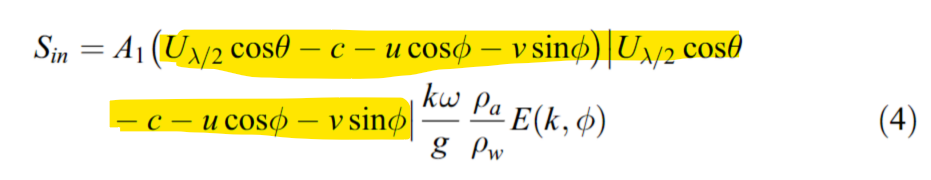

            % adjust input to lower value when waves overrun the wind (as wave speed approaches wind speed the energy extraction becomes less efficient)
            Ula = Ul; % saving a copy
            Ul = 0.11*Ul; % wind speed accounting for sheltering coefficient


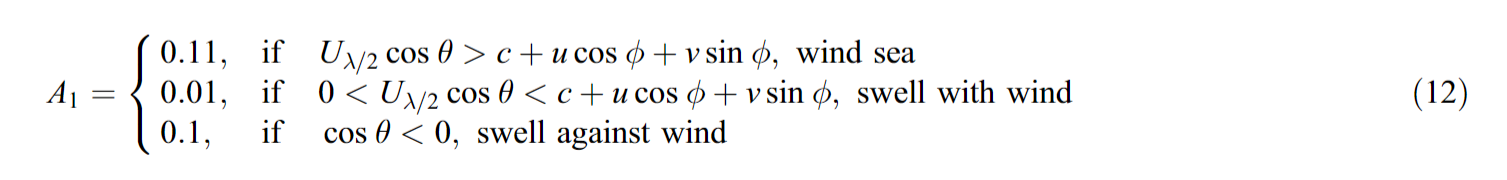

            Ul(Ul<0) = Ula(Ul<0)*0.03;% where is this fraction from?
            Ul(cos(windir-waveang)<0) = Ula(cos(windir-waveang)<0)*0.015;% Waves against wind.

 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Sin -- INPUT TERM

            % input to energy spectrum
            Sin = zeros(size(Ul)); % initialize input
            Sin(D>0) = rhorat*(Ul(D>0).*2*pi.*f(D>0).*wn(D>0)./(g+sfcT.*wn(D>0).*wn(D>0)./rhow));


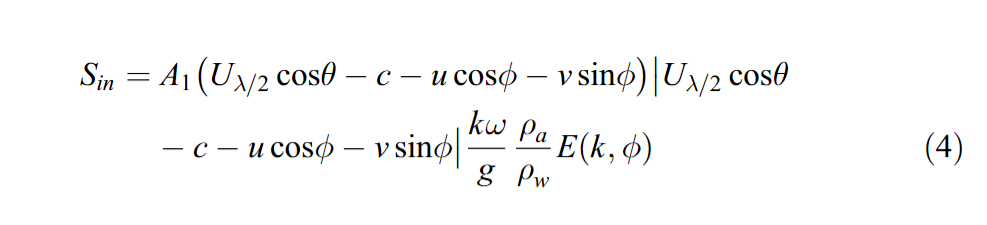

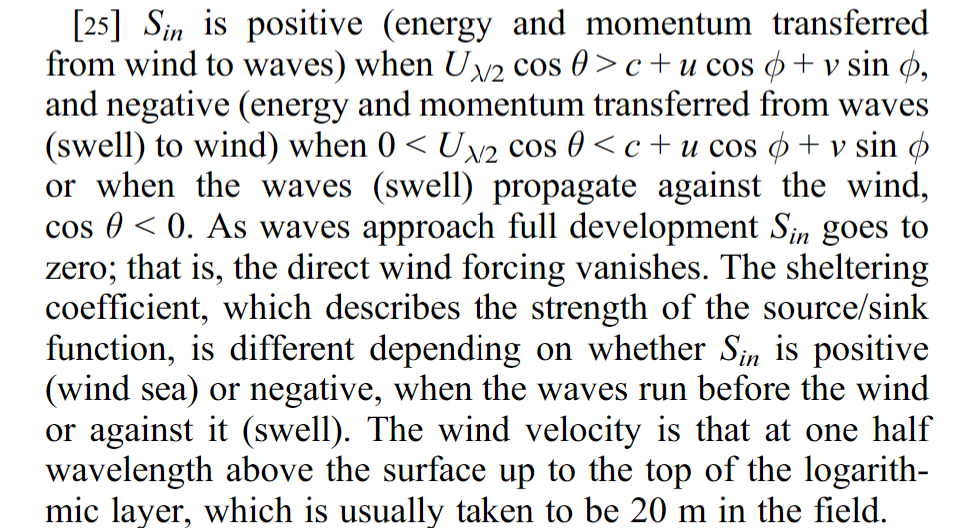

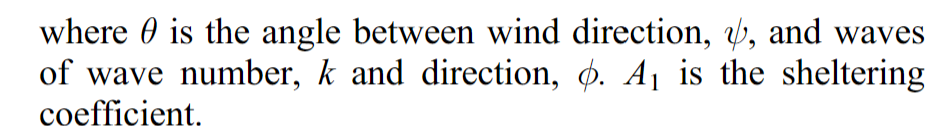

            % limit energy going into spectrum once waves outrun the wind by using a heavyside function
            Heavyside = ones(size(E)); % ones everywhere until waves outrun the wind
            Heavyside(Sin < 0 & E < 1e-320) = 0;  % zeroed out           
            Sin = Heavyside.*Sin;
            % set Sin = 0 at the land boundaries 
            Sin(D<=0) = 0;
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Sds -- DISSIPATION TERM

            for tj = 1:p
                short(:,:,:,tj) = sum(E.*cth2(:,:,:,rem([1:p]-tj+p,p)+1),4)*(360/p)*(pi/180); % something
            end
            short = (cumsum((wn.^3.*short.*dwn),3)-wn.^3.*short.*dwn); % integrated up

            % Calculate turbulent dissipation
            Sdt(:,:,:,:) = repmat(Ustar,[1 1 o p]);
            Sdt = Sdt_fac*sqrt(rhorat).*Sdt.*wn;


            % Calculate bottom friction
            Sbf = zeros(m,n,o,p); % initialize
            Sbf(D>0) = Sbf_fac*wn(D>0)./sinh(2*wn(D>0).*D(D>0));

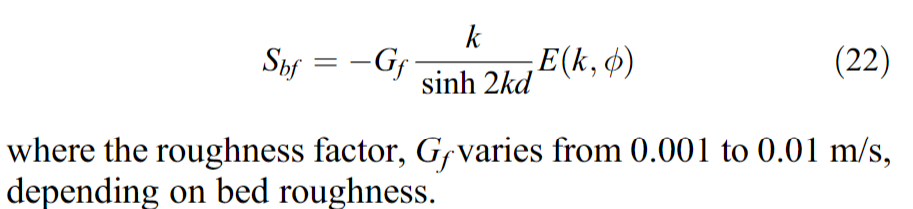

            % wave dissipation term
            Sds = zeros(size(Sin)); % initialize
            Sds(D>0) = abs(ann(D>0)*2*pi.*f(D>0).*(1+mss_fac*short(D>0)).^2.*(wn(D>0).^4.*E(D>0)).^(nnn(D>0)));


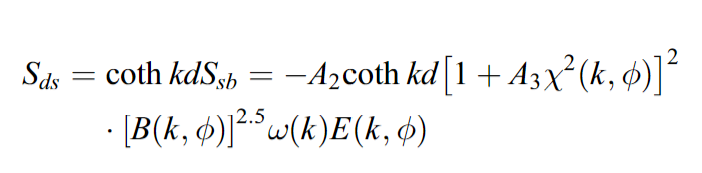

Includes: 

(1) Spectral saturation (k^-4 spectral fall off)

(2) Waves at spectral peak are steeper than in equilibrium (mean square slope of waves at spectral peak reduces the spectral densitioes in eqb relative to peak)

(3) Shoaling waves disspate more rapidly than spilling breaks. This limits the ratio of the breaker height to the depth of the shoaling wave.

            % set Sds = 0 at land boundaries
            Sds(D<=0) = 0; % LINE 469
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Snl -- NON-LINEAR TERM

            Snl = zeros(m,n,o,p); % initialize
            % Spread Snl to 2 next longer wavenumbers exponentially decaying as distance from donating wavenumber
            Snl(:,:,1:end-1,:) = bf1*Snl_fac*(Sds(:,:,2:end,:).*E(:,:,2:end,:).*wn(:,:,2:end,:).*dwn(:,:,2:end,:));
            Snl(:,:,1:end-2,:) = Snl(:,:,1:end-2,:) + bf2*Snl_fac*(Sds(:,:,3:end,:).*E(:,:,3:end,:).*wn(:,:,3:end,:).*dwn(:,:,3:end,:));
            % Renormalize to receiving wavenumber and bandwidth
            Snl(:,:,:,:) = Snl(:,:,:,:)./(wn(:,:,:,:).*dwn(:,:,:,:));
            Snl(:,:,:,:) = Snl(:,:,:,:) - Snl_fac*(Sds(:,:,:,:).*E(:,:,:,:));
            % set Snl = 0 at land
            Snl(D <= 0) = 0;
            
            % Sds_wc -- WHITE-CAPPING DISSIPATION

            Sds_wc = Sds; % make copy of dissipation term
            % Add viscous, turbulent and plunging dissipation after calculation of Snl
            Sds(D>0) = coth(0.2*wn(D>0).*D(D>0)).*Sds(D>0) + Sdt(D>0) + Sbf(D>0) + 4*nu*wn(D>0).^2;
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## TIME EVOLUTION FOR MODEL 

            aa = Sin(:,:,ol,:) - Sds(:,:,ol,:); % input - dissipation
            aa = aa(D(:,:,ol,:)>0); % ignore values on land
            aa = max(abs(aa(:))); % maximum difference between input and dissipation
            aaa = explim; % explim = 0.1 

            % if the dissipation term is zero then do something to aa term whatever that is
            if isnan(aa) == 1
                aa = aaa/maxdelt;
            end

            % new time evolution step (I think)
            newdelt = max([aaa/aa mindelt]);
            % newdelt = delt to give max of 50% growth or decay
            newdelt=min([newdelt maxdelt (Time-sumt) delt]);

            fprintf('newdelt: %.3f\n',newdelt);

            sumt = sumt + newdelt; % total time
            modt = modt + newdelt; % model time 
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## ENERGY SPECTRUM (PART ONE) -- Sin - 4*nu*k^2 - Sbg

            E1 = zeros(size(E)); % initialize 
            E2(:,:,:,:) = zeros(m,n,o,p); % intialize 
            cath = ones(size(Sds)); % intialize

            fac_exp=(Sin(:,:,ol,:) - Sds(:,:,ol,:)); % exponential term for long waves
            E1(:,:,ol,:) = E(:,:,ol,:).*exp(newdelt*fac_exp); % Long waves.
            E1(:,:,ol,:) = E1(:,:,ol,:) + newdelt*Snl(:,:,ol,:); % add nonlinear term
              
            cath(D>0)=coth(0.2*wn(D>0).*D(D>0));

            fij = find((Sin(:,:,:,:) - 4*nu*wn(:,:,:,:).^2 - Sdt(:,:,:,:) - Sbf(:,:,:,:)) > 0); % index where Sin - 4*nu*k^2 - Sbg is greater than zero
            E2(fij) = wn(fij).^(-4).*((Sin(fij)-4*nu*wn(fij).^2 - Sdt(fij) - Sbf(fij))./(cath(fij).*ann(fij)*2*pi.*f(fij).*(1+mss_fac*short(fij)).^2)).^(nnninv(fij)); 
            
            % set land boundaries to zero
            E2(D<=0) = 0;
            E1(D<=0) = 0;
            % set negative energy to zero
            E2(E2<0) = 0;
            E1(E1<0) = 0;

            E1(:,:,os,:) = E2(:,:,os,:);

            % energy term is complex but amplitude is real
            E1=real(E1);
            E1(E1 < 0)=0;
            % set land boundaries to zero
            E1(D <= 0)=0;
            E(D <= 0)=0;
            % E=(E+E1)/2
            E(:,:,os,:) = E1(:,:,os,:);
            E(:,:,ol,:) = (E(:,:,ol,:)+E1(:,:,ol,:))/2;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## ENERGY SPECTRUM (PART TWO) -- Advection term

            advect=zeros(m,n,o,p); % initialize advection
        
            Ccg = Cg + Uer.*cth + Uei.*sth; % group velocity

            % Upwave advection with account taken of varying delx and dely
            advect(:,:,ol,cp)=advect(:,:,ol,cp)+(Ccg(:,:,ol,cp).*cth(:,:,ol,cp).*E(:,:,ol,cp).*dely(:,:,ol,cp)...
                - Ccg(xp,:,ol,cp).*cth(xp,:,ol,cp).*E(xp,:,ol,cp).*dely(xp,:,ol,cp))...
                ./((dely(xp,:,ol,cp) + dely(:,:,ol,cp)).*(delx(xp,:,ol,cp) + delx(:,:,ol,cp)))*4;

            advect(:,:,ol,cm)=advect(:,:,ol,cm)+(Ccg(xm,:,ol,cm).*cth(xm,:,ol,cm).*E(xm,:,ol,cm).*dely(xm,:,ol,cm)...
                - Ccg(:,:,ol,cm).*cth(:,:,ol,cm).*E(:,:,ol,cm).*dely(:,:,ol,cm))...
                ./((dely(:,:,ol,cm) + dely(xm,:,ol,cm)).*(delx(:,:,ol,cm) + delx(xm,:,ol,cm)))*4;
            
            advect(:,:,ol,sp)=advect(:,:,ol,sp)+(Ccg(:,:,ol,sp).*sth(:,:,ol,sp).*E(:,:,ol,sp).*delx(:,:,ol,sp)...
                - Ccg(:,yp,ol,sp).*sth(:,yp,ol,sp).*E(:,yp,ol,sp).*delx(:,yp,ol,sp))...
                ./((dely(:,yp,ol,sp) + dely(:,:,ol,sp)).*(delx(:,yp,ol,sp) + delx(:,:,ol,sp)))*4;
            
            advect(:,:,ol,sm)=advect(:,:,ol,sm)+(Ccg(:,ym,ol,sm).*sth(:,ym,ol,sm).*E(:,ym,ol,sm).*delx(:,ym,ol,sm)...
                - Ccg(:,:,ol,sm).*sth(:,:,ol,sm).*E(:,:,ol,sm).*delx(:,:,ol,sm))...
                ./((dely(:,:,ol,sm) + dely(:,ym,ol,sm)).*(delx(:,:,ol,sm) + delx(:,ym,ol,sm)))*4;
            
            % include advection in energy calculation
            E1(:,:,ol,:) = E1(:,:,ol,:) - newdelt*advect(:,:,ol,:);

            % clean up energy term
            E1(D <= 0)=0; % set land boundaries to zero
            E1=real(E1); % real value amplitude
            E1(E1<0)=0; % negative energy to zero
            E1(D <= 0)=0; % land boundaries to zero
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## ENERGY SPECTRUM (PART THREE) -- ROTATION IN WAVE-CURRENT INTERACTION

            % Refraction including wave-current interaction
            Crot(:,:,ol,:)=(c(xm,:,ol,:)-c(xp,:,ol,:)).*sth(:,:,ol,:)./(delx(xm,:,ol,:)+delx(xp,:,ol,:))...
                -(c(:,ym,ol,:)-c(:,yp,ol,:)).*cth(:,:,ol,:)./(dely(:,ym,ol,:)+dely(:,yp,ol,:));
            
            % Determine if rotation is clockwise or counter clockwise
            Crotcw = zeros(size(Crot)); % initialize
            Crotccw = zeros(size(Crot)); % initialize

            Crotccw(Crot>0) = Crot(Crot>0); % if crot is positive then ccw rotation
            Crotcw(Crot<0) = Crot(Crot<0); % if crot is negative than cw rotation

            Crotccw(Crotccw > (360/p)/newdelt) = (360/p)/newdelt; % something
            Crotcw(Crotcw < -1*(360/p)/newdelt) = -1*(360/p)/newdelt; % something

            % include rotation term in energy spectrum
            E1(:,:,ol,cw) = E1(:,:,ol,cw) - newdelt*Crotcw(:,:,ol,:).*E(:,:,ol,:)/(360/p);
            E1(:,:,ol,:) = E1(:,:,ol,:) + newdelt*Crotcw(:,:,ol,:).*E(:,:,ol,:)/(360/p);
            E1(:,:,ol,ccw) = E1(:,:,ol,ccw) + newdelt*Crotccw(:,:,ol,:).*E(:,:,ol,:)/(360/p);
            E1(:,:,ol,:) = E1(:,:,ol,:) - newdelt*Crotccw(:,:,ol,:).*E(:,:,ol,:)/(360/p);

            % clean up energy term
            E1(E1 < 0)=0; % set negative energy to zero
            E1(D <= 0)=0; % set land boundaries to zero 
            E=real(E1); % only consider the real component amplitude
            E(isnan(E)) = 0; % set all nan balues to zero
            E1 = E; % what is the difference between E, E1, and E2?
            E(D <= 0)=0; % set land boundaries to zero
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## FORM STRESS SPECTRUM

            tauE = sum(wn.*E.*Sin.*cth./c,4)*(360/p)*(pi/180); % wind shear stress spectrum east 
            tauN = sum(wn.*E.*Sin.*sth./c,4)*(360/p)*(pi/180); % wind shear stress spectrum north

            mtail = 0.000112*U_10.*U_10 - 0.01451.*U_10 - 1.0186; % wind speed dependant tail of a slope pinned to the highest wavenumber
            wnh = squeeze(wn(:,:,o,1)); % highest wavenumber

            % include tail to spectrum
            tauE = rhow*(sum((g+sfcT.*squeeze(wn(:,:,:,1)).^2./rhow).*squeeze(dwn(:,:,:,1)).*tauE,3) + ...
                (g+sfcT.*squeeze(wn(:,:,o,1)).^2./rhow).*squeeze(tauE(:,:,o)).*wnh.^(-mtail).*(kutoff.^(mtail+1)-wnh.^(mtail+1))./(mtail+1)); % eastern spectrum
            tauN = rhow*(sum((g+sfcT.*squeeze(wn(:,:,:,1)).^2./rhow).*squeeze(dwn(:,:,:,1)).*tauN,3) + ...
                (g+sfcT.*squeeze(wn(:,:,o,1)).^2./rhow).*squeeze(tauN(:,:,o)).*wnh.^(-mtail).*(kutoff.^(mtail+1)-wnh.^(mtail+1))./(mtail+1)); % northern spectrum


            % frictional velocity at surface 
            Ustar_smooth = reshape(smooth_nu((1-wfac)*U_z(:),z,nua),m,n);
            Ustar_smooth = (Ustar_smooth./U_z).^2;
            Ustar_smooth = U_z.^2.*(0.3333*Ustar_smooth + 0.6667*(Ustar_smooth.^2)./(Ustar_smooth + Cd));

            %Cds =  Ustar_smooth; % save a copy

            % include the frictional velocity term in the shear stress
            tauE = tauE + rhoa*Ustar_smooth.*cos(squeeze(windir(:,:,1,1))); % shear stress to east 
            tauN = tauN + rhoa*Ustar_smooth.*sin(squeeze(windir(:,:,1,1))); % shear stress to north 

            % from the definition of shear stress and law of the wall
            Cd = abs(tauE + 1i*tauN)./rhoa./(U_z.^2); % stress coefficient
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## SIGNIFIGANT HEIGHT & MEAN SLOPE RESULT

            % Integrate spectrum to find significant height 
            ht = sum(dwn.*wn.*E,4)*(360/p)*(pi/180);
            ht = sum(ht,3);
            ht = 4*sqrt(abs(ht));

            % Integrate spectrum to find mean slope 
            ms = sum(dwn.*wn.^3.*E,4)*(360/p)*(pi/180);
            ms = sum(ms,3);
            ms = sqrt(ms);
            
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## PEAK FREQUENCY

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## PLOTTING

           %if rem(tplot,10) == 0 % plot every 10th time step
                
                % Omnidirectional wavenumber spectrum 
                figure;
                semilogx(squeeze(wn(2,lati,:,p/2)),squeeze(sum(wn([2:4:m],lati,:,:).*E([2:4:m],lati,:,:),4)*(360/p)*(pi/180))','*-');
                grid on;
                title(['Omni directional wavenumber spectra along latitude ',num2str(lati),'. Time = ',num2str(modt/3600),' Hours'])
                
                % SUBPLOTS:
                % (1) Drag coefficient vs Fetch
                figure;
                subplot(321);
                plot(Cd(:,lati).*(U_z(:,lati)./U_10(:,lati)).^2,'.-');
                xlabel('Fetch')
                ylabel('Drag Coefficient')
                grid on;
                
                % (2) k*Sin
                subplot(322);
                semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Sin(long,lati,:,:).*E(long,lati,:,:),4))*(360/p)*(pi/180),'*-');
                title('k*Sin');
                grid on;
                
                % (3a) k*Sds(b) 
                subplot(323);
                semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Sds(long,lati,:,:).*E(long,lati,:,:),4))*(360/p)*(pi/180),'*-');
                hold on;
                
                % (3b) k*Sdt(g)
                subplot(323);
                semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Sdt(long,lati,:,:).*E(long,lati,:,:),4))*(360/p)*(pi/180),'*-g');
                
                % (3c) k*Sbf(r)
                subplot(323);
                semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Sbf(long,lati,:,:).*E(long,lati,:,:),4))*(360/p)*(pi/180),'*-r');
                title('k*Sds(b), k*Sdt(g), k*Sbf(r)');
                grid on
                hold off;

                % (4) k*Snl
                subplot(324);
                semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*Snl(long,lati,:,:),4))*(360/p)*(pi/180),'*-');
                title('k*Snl');
                grid on;

                % (5) k*Spectrum
                subplot(325);
                semilogx(squeeze(wn(long,lati,:,10)),squeeze(sum(wn(long,lati,:,:).^2.*E(long,lati,:,:),4))*(360/p)*(pi/180),'*-');
                title('k*spectrum');
                grid on;

                % (6) Sig H and Mean Slope
                subplot(326);
                plot(1:m,ht(:,lati),'.-')
                hold on;
                plot(1:m,ms(:,lati),'--r')
                hold off;
                title('Sig H and Mean Slope')
                grid on;

                % Signifigant Height 
                [xplot,yplot] = meshgrid(1:m,1:n);
                figure;
                surf(xplot',yplot',ht,'EdgeColor','k')
                myc = colorbar;
                myc.Label.String = 'Sig H [m]';
                title(['Sig Wave Height for u = ',num2str(UUvec(iii)),' m/s'])
                frame = getframe(gcf);
                im{idx} = frame2im(frame);
                idx = idx + 1;

                % Integrate spectrum  over wavenumber to plot directional plot of 10th wavelength
                Wavel = sum(squeeze(wn(:,:,10,:)).*squeeze(E(:,:,10,:).*dwn(:,:,10,:)),3)./sum(squeeze(E(:,:,10,:).*dwn(:,:,10,:)),3);
                Wavel = 2*pi./Wavel;Wavel = Wavel.^(0.25); % Wavelength to 1/4 power
                % Direction of one wavelength
                KD = squeeze(sum(dwn(:,:,10,:).*E(:,:,10,:),3));
                Dir_sin = sum(KD.*squeeze(sin(waveang(:,:,10,:))),3)./sum(KD,3);
                Dir_cos = sum(KD.*squeeze(cos(waveang(:,:,10,:))),3)./sum(KD,3); 
                mdir = atan2(Dir_sin,Dir_cos);
                
                figure;
                quiver(Wavel'.*cos(mdir'),Wavel'.*sin(mdir'),0.8,'c');
                title(['Sig.Ht. and \lambda^{1/4}. Time = ',num2str(modt/3600),' Hours'])
                
                figure;
                contour(ht',20)
                myc = colorbar;
                myc.Label.String = 'Sig H [m]';
                grid on;
                title(['Sig.Ht. Time = ',num2str(modt/3600),' Hours'])

                
           %end
           close all;
           cgmax = max(max(max(max((E>1e-320).*Cg)))); % Adjust cgmax for active energy components
            
        end

        % print time update to screen 
        fraction_time_completed = t/Tsteps;
        ttime=toc;
        hours_to_complete = Tsteps/t*ttime/3600;

        fprintf('fraction time completed: %.2f\n',fraction_time_completed);
        fprintf('Seconds so far: %i\n',ttime);
        fprintf('Hours remaining: %.2f\n',hours_to_complete);

        % save data from loop to .mat file
        eval(['save Titan/Titan_',int2str(file),'_',int2str(t),' E ht f oa Cd Sds Sds_wc Sin Snl Sdt Sbf ms'])

    end

    % print wind speeds completed so far to screen
    %[minval,minind] = min(abs(UUvec-U));
    %disp(['Finished Wind Speed ' num2str(UU) ' m/s (' num2str(minind) ' Of ' num2str(numel(UUvec)) ' )']);

end

## make gif of results

idx_end = idx;
filename = 'SigH.gif'; % Specify the output file name
for idx = 1:idx_end-1
    [A,map] = rgb2ind(im{idx},256);
    if idx == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',1);
    else
        imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',1);
    end
end
diary off; % close logging function